# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['G:\Shrey\silent_wm_e02\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 3 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                       % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['G:\Shrey\silent_wm_e02\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type       = 'swmv2_definetrial2'  

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 3
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]


Deci.DT.Starts     = {100};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {101};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[11]}; % Time of Interest, be sure to include larger window for freq
Deci.DT.Locks      = [11 17];
Deci.DT.Toi        = [-1 6];

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [1 60];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-0.25 1.25];   
Deci.Art.AddComponents =  false;

## 4. Analysis

## 5. Plotting

## ** 6. Run**

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 3
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]
            ICA: [1×1 struct]
            Art: [1×1 struct]
            Run: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]


Running Deci for 1 subjects
 
----------------------
Starting Artifactor for Subject #1: swm06_full
 
---ICA---
 


Manual ICA Rejection
Found 2 eye-correlated components


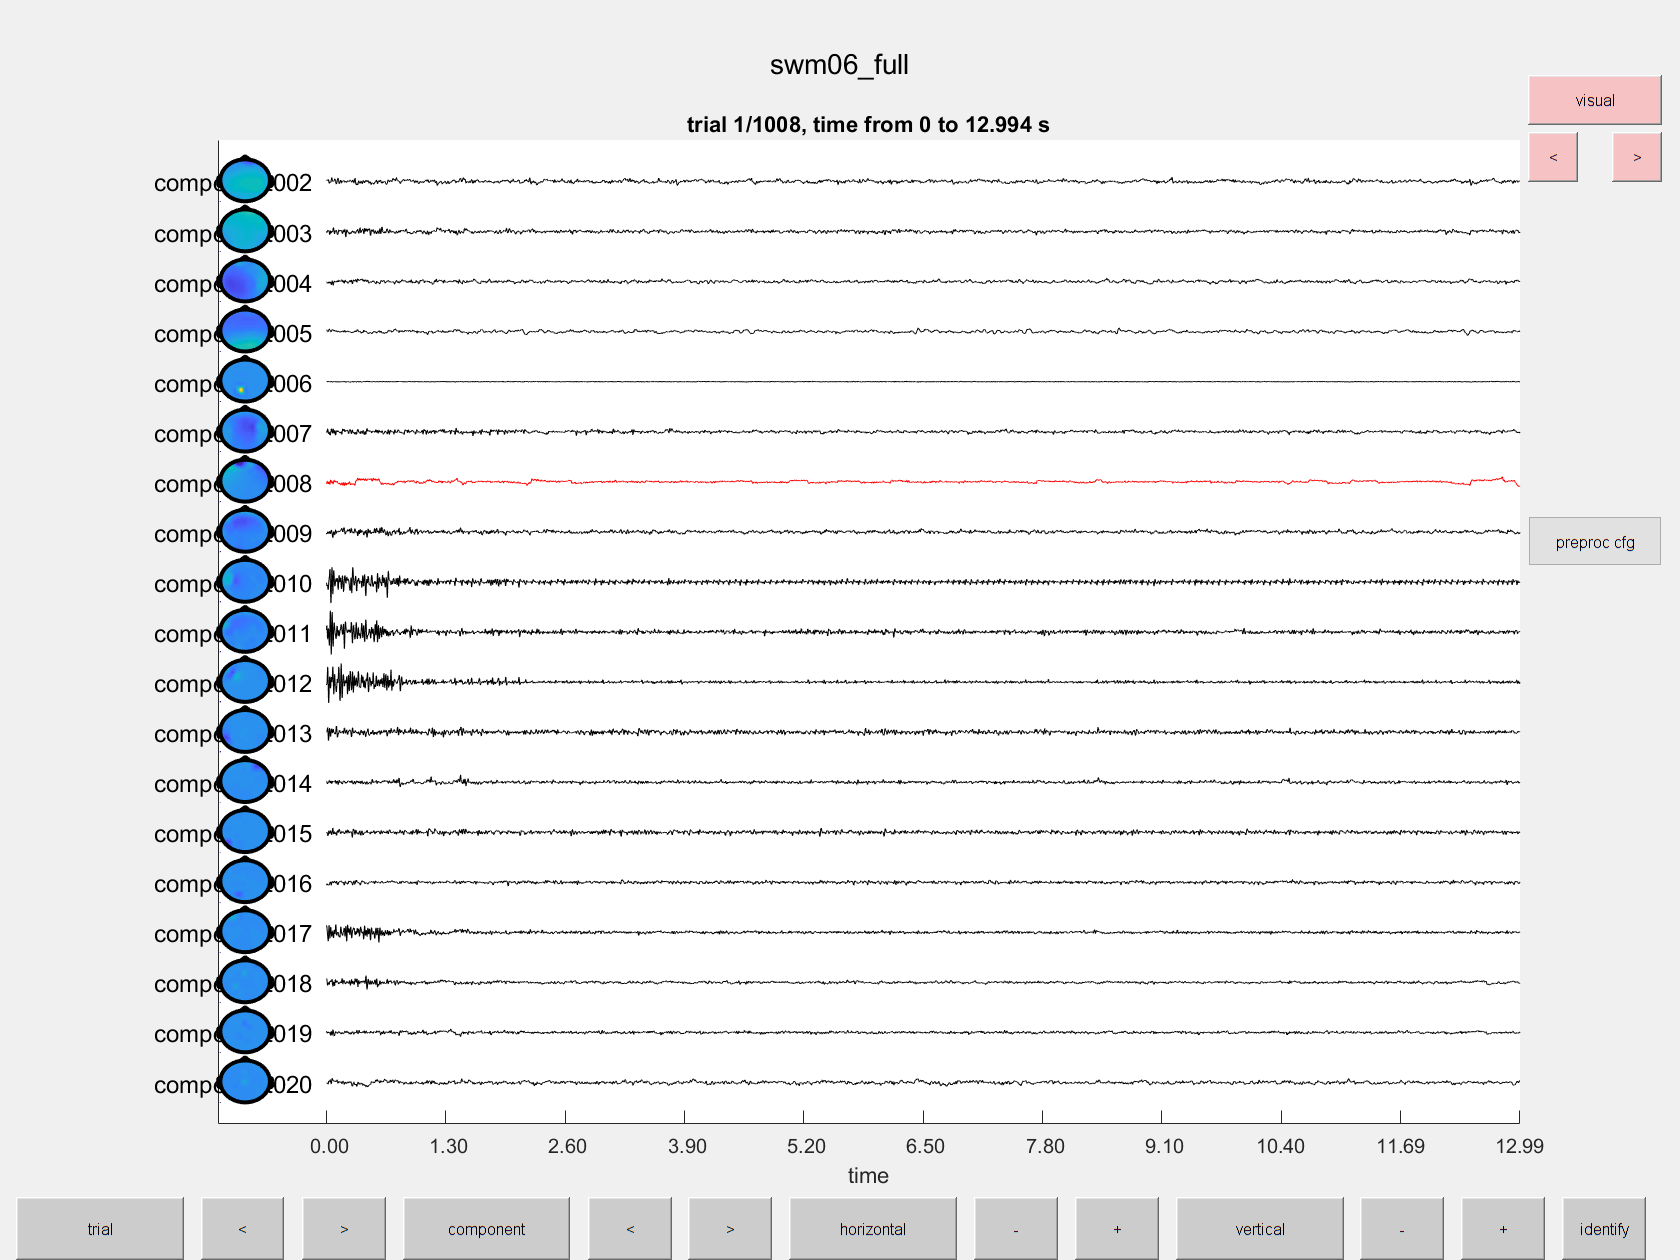

LockTypes = {'Instru_StimLocked','Instru_StimLocked_Hemi', 'Instru_RspLocked', 'Instru_RspLocked_Hemi', 'Instru_FdbLocked','Instru_FdbLocked_Hemi'};
%LockTypes = {'Instru_StimLocked_Hemi','Instru_RspLocked_Hemi','Instru_FdbLocked_Hemi'};
%LockTypes = {'Instru_StimLocked','Instru_StimLocked_Hemi'};
Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

if Deci.Step == 4
    for AnalysisLocks = LockTypes
        Deci_Wavelet;
        eval(AnalysisLocks{1})
        
        
        
        Deci.Analysis.ERP.do  = true;
        Deci.Analysis.Freq.do  = true;
        Deci.Analysis.Extra.do  = true;
        
        Deci_Backend(Deci);
    end
else
    
    Instru_FdbLocked;
    Deci.Plot.BslRef = 'Stim Onset';
    Deci.Plot.Lock = 'Stim Onset';
    
    Deci.Plot.GrandAverage = false;
    
    Deci.Plot.Freq.Topo.do    =false;
    Deci.Plot.Freq.Topo.Foi     = [9 13];                   % Frequency of Interest
    Deci.Plot.Freq.Topo.Toi     = [0 1];                   % Time of Interest
    Deci.Plot.Freq.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Freq.Square.do  =true;
    Deci.Plot.Freq.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Freq.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Freq.Wire.do    =false;
    Deci.Plot.Freq.Wire.Foi     =   [4 7.5];          % Frequency of Interest
    Deci.Plot.Freq.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Wire.Channel = [{'Cz'}];              % Channel of Interest
    
    Deci.Plot.Freq.Bar.do    =false;
    Deci.Plot.Freq.Bar.Foi     = [9 13];                 % Frequency of Interest
    Deci.Plot.Freq.Bar.Toi     = [0 1];                   % Time of Interest
    Deci.Plot.Freq.Bar.Channel =  [{'PO8'}];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower'; 
    
    if  strcmpi(Deci.Plot.BslRef, 'Response Onset')
        Deci.Plot.Freq.Bsl     = [-.5 -.3];
    else
        Deci.Plot.Freq.Bsl     = [-.5 0];
    end
    
    Omnibus = true;
    
    if Omnibus == true
        Deci.Plot.Stat.Comp = 'Bsl';
        Deci.Plot.Stat.alpha = .01;
        %Deci.Plot.Stat.correctm = 'fdr';
        Deci.Plot.Freq.BslType = 'relchange'
    end

    Deci_Backend(Deci);
end